# Representative Signal Chain

## User parameters

clear all; close all;
% Camera
p.fl    = 0.5;      %[m] focal length
p.dApp  = 0.1;      %[m] Apperture Diameter
p.p     = 5e-6;     %[m] pixel pitch
p.cnt   = 1e3;      %[#] sqrt of number of pixels
p.rate  = [3,50];   %[hz] frame rate of imagery

p = struct with fields:
      fl: 0.5000
    dApp: 0.1000
       p: 5.0000e-06
     cnt: 1000
    rate: [3 50]


p.int   = [5e-2,5e-3];%[s] integration time

p = struct with fields:
      fl: 0.5000
    dApp: 0.1000
       p: 5.0000e-06
     cnt: 1000
    rate: [3 50]
     int: [0.0500 0.0050]


p.well  = 20000;    %[electrons] well depth
p.bitD  = 16;       %[bits] Bit Depth
p.dcOff = 50;       %[DC] DC offset
p.bgIrr = 1e-6;     %[w/m2/bp] Irradiance on the FP, ideally this would be from a series of simulation 
p.cwl   = 600e-9;   %[m] center wavelength
p.bp    = 400e-9;   %[m] bandpass width 
p.fpIrr = 1e-11;     %[w/m2/bp] Focalplane irradiance from straylight

p = struct with fields:
       fl: 0.5000
     dApp: 0.1000
        p: 5.0000e-06
      cnt: 1000
     rate: [3 50]
      int: [0.0500 0.0050]
     well: 20000
     bitD: 16
    dcOff: 50
    bgIrr: 1.0000e-06
      cwl: 6.0000e-07
       bp: 4.0000e-07
    fpIrr: 1.0000e-11


p.radStd= 1000;      %[pixels] Std of radial fall off of straylight

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 0.0050]
      well: 20000
      bitD: 16
     dcOff: 50
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
     fpIrr: 1.0000e-11
    radStd: 1000



% engagement
p.engPhs= 90;   %[deg] Phase angle between sensor and target velocity vectors
p.POCA  = 5e3;  %[m] Seperation of target and sensor at point of closest approach
p.lPOCA = [0,7000e3,0];%[m] Locating Poca location

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 0.0050]
      well: 20000
      bitD: 16
     dcOff: 50
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
     fpIrr: 1.0000e-11
    radStd: 1000
    engPhs: 90
      POCA: 5000
     lPOCA: [0 7000000 0]


p.rImg  = 30e3; %[s] range which we switch integration 
p.rStart= 840e3;%[m] range from Poca we start the engagement
p.dTgt  = 5;    %[m] Diameter of target
p.rfl   = 1;    %[ratio] reflectance   

% Simulation Params
p.mBuf  = 10;   %[pixels] How much motion we'll allow
p.strOSF= 17;   %[scl] determines how much we'll oversample the psf for the stars
p.tgtOSF= 3;    %[tgt] determines how much we'll over sample the target
p.bgShp = .4;   %[] drives how quickly the SL falls off >1 quicker, <1 slower, 1 = radially
p.maxMag= 13;   %[] drives max mag of those stars (3x drop in stars/mag)
p.strSz = 7;    %[] %KEEP ODD
p.bgMem = 50;   %[] How many backgrounds we have to randomly draw from;

%constants
p.mV_sun = -26.74;

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 0.0050]
      well: 20000
      bitD: 16
     dcOff: 50
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
     fpIrr: 1.0000e-11
    radStd: 1000
    engPhs: 90
      POCA: 5000
     lPOCA: [0 7000000 0]
      rImg: 30000
    rStart: 840000
      dTgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     strSz: 7
     bgMem: 50
    mV_sun: -26.7400


p.cLight = 2.99792458e8;

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 0.0050]
      well: 20000
      bitD: 16
     dcOff: 50
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
     fpIrr: 1.0000e-11
    radStd: 1000
    engPhs: 90
      POCA: 5000
     lPOCA: [0 7000000 0]
      rImg: 30000
    rStart: 840000
      dTgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     strSz: 7
     bgMem: 50
    mV_sun: -26.7400
    cLight: 299792458


p.hPlank = 6.62607015e-34

p = struct with fields:
        fl: 0.5000
      dApp: 0.1000
         p: 5.0000e-06
       cnt: 1000
      rate: [3 50]
       int: [0.0500 0.0050]
      well: 20000
      bitD: 16
     dcOff: 50
     bgIrr: 1.0000e-06
       cwl: 6.0000e-07
        bp: 4.0000e-07
     fpIrr: 1.0000e-11
    radStd: 1000
    engPhs: 90
      POCA: 5000
     lPOCA: [0 7000000 0]
      rImg: 30000
    rStart: 840000
      dTgt: 5
       rfl: 1
      mBuf: 10
    strOSF: 17
    tgtOSF: 3
     bgShp: 0.4000
    maxMag: 13
     strSz: 7
     bgMem: 50
    mV_sun: -26.7400
    cLight: 299792458
    hPlank: 6.6261e-34


## Read in data and create LUTs

% Generate a PRP for our stars (Note: for a system with a changing Focus to
% keep up with the target, this would be an LUT)
[psf, x, y] = diffraction_psf(p.p/p.strOSF, p.fl/p.dApp,p.cwl); % get diffraction psf for CWL
prp0 = conv2(psf,ones(p.strOSF),'same'); %turn it into a prp
s.strPRP.dat = padarray(prp0,[1 1]*round(p.mBuf *p.strOSF/2),0,'both'); %pad array for motion
% store indexing for future use. 
s.strPRP.idx = round(size(s.strPRP.dat,1)/2) + p.strOSF*[-floor(p.strSz/2):floor(p.strSz/2)];
s.strPRP.idxIm = [-floor(p.strSz/2):floor(p.strSz/2)];
% if 1;figure; subplot(1,2,1);imagesc(s.strPRP.dat);subplot(1,2,2);imagesc(s.tgtPRP.dat); end;

% %Do the same thing for our target. (Note: This should be a LUT based on
% %the focus of the system and the range of the target)
% [psf, x, y] = diffraction_psf(p.p/p.tgtOSF, p.fl/p.dApp,p.cwl); % get diffraction psf for CWL
% prp0 = conv2(psf,ones(p.tgtOSF),'same'); %turn it into a prp
% s.tgtPRP.dat = padarray(prp0,[1 1]*round(p.mBuf *p.tgtOSF/2),0,'both'); %pad array for motion

%Generate a star LUT
s.starLUT = star_lut(p.maxMag,1); %This will just give a rough

res = 0.0100

samples =    13.0000   12.9900   12.9800   12.9700   12.9600   12.9500   12.9400   12.9300   12.9200   12.9100   12.9000   12.8900   12.8800   12.8700   12.8600   12.8500   12.8400   12.8300   12.8200   12.8100   12.8000   12.7900   12.7800   12.7700   12.7600   12.7500   12.7400   12.7300   12.7200   12.7100   12.7000   12.6900   12.6800   12.6700   12.6600   12.6500   12.6400   12.6300   12.6200   12.6100   12.6000   12.5900   12.5800   12.5700   12.5600   12.5500   12.5400   12.5300   12.5200   12.5100


starLUT =          0         0   12.9851
         0         0   12.3907
         0         0   12.6161
         0         0   12.7113
         0         0   12.5009
         0         0   11.9662
         0         0   12.6975
         0         0   12.2165
         0         0   12.8812
         0         0   12.7767



%get sun irrad
dat = readtable('SolarSpec.txt');
wl = dat.Wavelength_nm_*1e-9;
idx = find((wl>(p.cwl-p.bp/2))==(wl<(p.cwl+p.bp/2)));
s.sun = trapz(dat.Wavelength_nm_(idx),dat.Extraterrestrial_W_m2_nm_(idx)); 

%basic figures of me
s.ifov = p.p/p.fl;  %pixel fov
s.fov  = s.ifov*p.cnt; %system field of view
s.cSA  = pi/(4*(p.fl/p.dApp)^2); %Collecting solid angle (gnum/trans)
s.qse  = p.well/2^p.bitD;
s.rdN  = p.well/(sqrt(12)*2^p.bitD);
s.e2dc = @(eIm) uint16((normrnd(eIm*0,s.rdN).^2+poissrnd(eIm).^2).^0.5/s.qse+p.dcOff);

%Set up bg stuff
[rx,ry]     = meshgrid([linspace(-p.cnt/2,p.cnt/2,p.cnt)]);
r           = sqrt(rx.^2+ry.^2);
bgIrr       = normpdf(r,0,p.radStd).*p.fpIrr;
for i = 1:length(p.int)
    s.bgSig{i}  = bgIrr.*p.cwl/p.hPlank/p.cLight*p.int(i).*pi*(p.dApp^2)/4;
    s.bgBase{i} = s.e2dc(repmat(s.bgSig{i},[1,1,p.bgMem]));
end

%some place holders
s.sig = zeros(p.cnt)

s = struct with fields:
     strPRP: [1×1 struct]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
        qse: 0.3052
        rdN: 0.0881
       e2dc: @(eIm)uint16((normrnd(eIm*0,s.rdN).^2+poissrnd(eIm).^2).^0.5/s.qse+p.dcOff)
      bgSig: {[1000×1000 double]  [1000×1000 double]}
     bgBase: {[1000×1000×50 uint16]  [1000×1000×50 uint16]}
        sig: [1000×1000 double]


## Generate engagements

% set up relative speeds (assuming everything in space goes 7Km/s)
s.vSens   = [7e3,0,0];
s.vTgt    = [cosd(p.engPhs),0,sind(p.engPhs)]*7e3;

%calc engagement range
s.xSens(1,:) = p.lPOCA-[p.rStart, 0, 0];
s.xTgt(1,:)  = p.lPOCA-[cosd(p.engPhs)*p.rStart,-p.POCA,sind(p.engPhs)*p.rStart];
mode = 1

mode = 1

i = 1

i = 1

s.t(1) = 0

s = struct with fields:
     strPRP: [1×1 struct]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
        qse: 0.3052
        rdN: 0.0881
       e2dc: @(eIm)uint16((normrnd(eIm*0,s.rdN).^2+poissrnd(eIm).^2).^0.5/s.qse+p.dcOff)
      bgSig: {[1000×1000 double]  [1000×1000 double]}
     bgBase: {[1000×1000×50 uint16]  [1000×1000×50 uint16]}
        sig: [1000×1000 double]
      vSens: [7000 0 0]
       vTgt: [0 0 7000]
      xSens: [-840000 7000000 0]
       xTgt: [0 7005000 -840000]
          t: 0


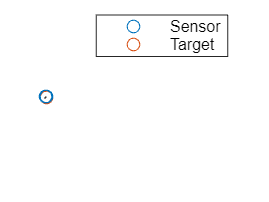

s.tMode(1) = mode;
while mode ~=3
    i = i+1;
    s.tMode(i)   = mode;
    s.t(i)       = s.t(i-1)+1/p.rate(mode);    
    s.xSens(i,:) = s.xSens(i-1,:)+s.vSens.*1/p.rate(mode);
    s.xTgt(i,:)  = s.xTgt(i-1,:)+s.vTgt.*1/p.rate(mode);
    if mode == 1 && norm(s.xTgt(i,:)-p.lPOCA)<p.rImg
        mode = mode +1;
    elseif mode == 2 && norm(s.xTgt(i,:)-p.lPOCA)>p.rImg
        mode = mode +1;
    end
end
  
% show motion
if 1; figure;
scatter3(s.xSens(:,1),s.xSens(:,2),s.xSens(:,3)); hold on; 
scatter3(s.xTgt(:,1),s.xTgt(:,2),s.xTgt(:,3));
axis equal
legend({'Sensor','Target'}); xlabel('x');ylabel('y');zlabel('z')
end


%% Get Pointing
dx  = s.xTgt - s.xSens;
dv  = repmat(s.vTgt - s.vSens,[length(dx),1]);
los = dx(:,1:3) ./ vecnorm(dx(:,1:3),2,2);
omega   = cross(dx(:,1:3),dv,2) ./ dot(dx(:,1:3),dv,2);
omega_poca = omega ./ sqrt(sum(omega.^2, 2));
oz_des  = omega_poca;
oy_des  = cross(oz_des, los, 2); oy_des = oy_des ./ vecnorm(oy_des,2,2);
ox_des  = cross(oy_des, oz_des, 2);
R_desHat= pagetranspose(reshape([ox_des oy_des oz_des]',3,3,[]));
s.tQ      = dcm2quat(R_desHat); %direction cosine matric to quaternions

% Get RaDec for optical axes
opticAx = quatrotate(quatconj(s.tQ),[1,0,0]);
s.tRadDec = [atan2(opticAx(:,2),opticAx(:,1)),...
    asin(opticAx(:,3))];
s.tRadDec(:,1) = s.tRadDec(:,1)

s = struct with fields:
     strPRP: [1×1 struct]
    starLUT: [1605121×3 double]
        sun: 644.7140
       ifov: 1.0000e-05
        fov: 0.0100
        cSA: 0.0314
        qse: 0.3052
        rdN: 0.0881
       e2dc: @(eIm)uint16((normrnd(eIm*0,s.rdN).^2+poissrnd(eIm).^2).^0.5/s.qse+p.dcOff)
      bgSig: {[1000×1000 double]  [1000×1000 double]}
     bgBase: {[1000×1000×50 uint16]  [1000×1000×50 uint16]}
        sig: [1000×1000 double]
      vSens: [7000 0 0]
       vTgt: [0 0 7000]
      xSens: [761×3 double]
       xTgt: [761×3 double]
          t: [0 0.3333 0.6667 1 1.3333 1.6667 2.0000 2.3333 2.6667 3 3.3333 3.6667 4 4.3333 4.6667 5.0000 5.3333 5.6667 6.0000 6.3333 6.6667 7.0000 7.3333 7.6667 8.0000 8.3333 8.6667 9.0000 9.3333 9.6667 10 10.3333 10.6667 11.0000 … ] (1×761 double)
      tMode: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1

clearvars -except s p %just keeping our workspace tidy

## Simulate Engagement

% set bounds for which stars we'll keep in analysis
buf = sqrt(sum(s.fov.^2))*2

buf = 0.0200

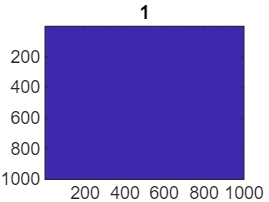


figure
for t = 1:length(s.t)
    s.SIG = s.bgBase{s.tMode(t)}(:,:,ceil(rand*p.bgMem));
    %% Set up stars from FOV
    raBnd1 = s.tRadDec(t,1)+[-1,1]*buf;
    decBnd = s.tRadDec(t,2)+[-1,1]*buf;
    
    % If RA bounds roll over at all, create another bounp.motionSamd which we'll check. 
    if raBnd1(1)<-pi 
        raBnd2=[raBnd1(1)+2*pi,pi];
    elseif raBnd1(2)>pi
        raBnd2=[-pi,raBnd1(2)-2*pi];
    else
        raBnd2=raBnd1;
    end
    
    %%%%%% create library of stars that are near the FOV
    idx = find((((s.starLUT(:,1)>raBnd1(1)) & (s.starLUT(:,1)<raBnd1(2))) |...
        ((s.starLUT(:,1)>raBnd2(1)) & (s.starLUT(:,1)<raBnd2(2)))) &...
        ((s.starLUT(:,2)>decBnd(1)) & (s.starLUT(:,2)<decBnd(2))));
    stars = s.starLUT(idx,:);

    % Create unit vector for stars so that we can rotate this vector
    % from reported J2000 GCRS frame to the instantaneous MOD frame
    starV = [cos(stars(:,1)).*cos(stars(:,2)) ...
        sin(stars(:,1)).*cos(stars(:,2)) ...
         sin(stars(:,2))];


    %%%%%%% rotate stars to optical frame and turn into pixel coords
    starP = quatrotate(s.tQ(t,:), starV);
    x = starP(:,2)./starP(:,1); % [rad,p] Yp becomes FP_col "left"
    y = starP(:,3)./starP(:,1); % [rad,p] Zp becomes FP_row "up"
    %get in units of FOVs, then scale to pixels
    px = (-y/s.fov+0.5)*p.cnt-0.5;
    py = (-x/s.fov+0.5)*p.cnt-0.5;

    %%%%%%% get motion vector by looking at raDec pointing
    % frame and this frame. 
    di = 0; % These become a vector of points to sample the motion. 
    dj = 0;
    if (p.mBuf>1) & t>1                
        % get the RaDec looking point
        pt =   [cos(s.tRadDec(t,1)).*cos(s.tRadDec(t,2)) ...
                sin(s.tRadDec(t,1)).*cos(s.tRadDec(t,2)) ...
                 sin(s.tRadDec(t,2))];         
        %rotate current looking point by last quaternion             
        starP0 = quatrotate(s.tQ(t-1,:), pt); % look at our current quat rotated to our center point
        x0 = starP0(:,2)./starP0(:,1); % [rad] Yp becomes FP_col 
        y0 = starP0(:,3)./starP0(:,1); % [rad] Zp becomes FP_row 
        %get in units of FOVs, then scale to pixels
        px0 = (-y0/s.fov+0.5)*p.cnt-0.5;
        py0 = (-x0/s.fov+0.5)*p.cnt-0.5;
        
        % get difference in location in pixels 
        dt = s.t(t)-s.t(t-1);
        dx = (p.cnt/2 - px0)*dt;
        dy = (p.cnt/2 - py0)*dt;
        di = round(p.strOSF*linspace(-dx/2,dx/2,p.mBuf));
        dj = round(p.strOSF*linspace(-dy/2,dy/2,p.mBuf));
        blur = sum([dx,dy].^2)^.5;

    end            
    % get only the stars contained within FOV. 
    f = (px > 0) & (py > 0) & (px<p.cnt) & (py<p.cnt);
    px = px(f);
    py = py(f);
    
    % turn into irradiance and then electrons
    irrApp = s.sun*10.^(-(stars(f,3)-p.mV_sun)/2.5);
    elec   = irrApp.*p.cwl/p.hPlank/p.cLight*p.int(s.tMode(t)).*pi*(p.dApp^2)/4; 
    % get pixel locations    
    I = round(px);
    J = round(py);
    % and phasing for PRP
    i = round(p.strOSF*(px-I));
    j = round(p.strOSF*(py-J));

    % build image
    SZ = [p.cnt,p.cnt];
    for str = 1:length(elec); 
        if p.mBuf>1 && t>1
            sz = size(s.strPRP.dat);
            for ii = 1:length(s.strPRP.idx)
                for jj = 1:length(s.strPRP.idx)
                    iii = s.strPRP.idx(ii)+i(str)+di; iii(iii<1) = 1; iii(iii>sz(1)) = sz(1);
                    jjj = s.strPRP.idx(jj)+j(str)+dj; jjj(jjj<1) = 1; jjj(jjj>sz(2)) = sz(2);
                    prp(ii,jj) = mean(s.strPRP.dat(iii,jjj),'all');
                end
            end
        else
            prp = s.strPRP.dat(s.strPRP.idx+i(str),s.strPRP.idx+j(str));
        end

        %get rid of pixels that go beyond boarders of image;
        II = s.strPRP.idxIm+I(str); JJ = s.strPRP.idxIm+J(str); 
        indi = find(~((II<SZ(1)).*(II>1))); indj = find(~((JJ<SZ(2)).*(JJ>1)));
        II(indi) = []; JJ(indj) = [];
        prp(indi,:) = []; prp(:,indj) = [];
        star = prp.*elec(str);
        s.SIG(II,JJ) = s.e2dc(s.bgSig{s.tMode(t)}(II,JJ)+star);
    end 
    imagesc(s.SIG); title(num2str(t)); drawnow; pause(0.1)
end

## Functions

% Generate a psf
function [psf, x, y] = diffraction_psf(pixel_pitch, f_number, wavelength)
    % Generates the diffraction-limited point spread function (PSF).
    
    % Input arguments:
    %   pixel_pitch: Pixel pitch in meters.
    %   f_number: f-number of the optical system.
    %   wavelength (optional): Wavelength of light in meters. Defaults to 550nm.
    
    % Output arguments:
    %   psf: The PSF array.
    %   x: The x-coordinates of the PSF grid.
    %   y: The y-coordinates of the PSF grid.
    
    if nargin < 3
        wavelength = 550e-9; % Default wavelength: green light
    end
    
    % Calculate the Airy disk radius (first minimum)
    airy_radius = 1.22 * wavelength * f_number;
    
    % Create a grid for the PSF
    psf_size = ceil(6 * airy_radius / pixel_pitch); % Size of the PSF array
    if mod(psf_size, 2) == 0  % Ensure psf_size is odd for centering
        psf_size = psf_size + 1;
    end
    
    x = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    y = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    [X, Y] = meshgrid(x, y);
    r = sqrt(X.^2 + Y.^2);
    
    % Calculate the PSF using the Airy disk formula
    psf = zeros(size(r));
    nonzero_r = r > 0;
    psf(nonzero_r) = (2 * besselj(1, pi * r(nonzero_r) / airy_radius) ./ (pi * r(nonzero_r) / airy_radius)).^2;
    psf(r == 0) = 1.0; % Central maximum
    
    % Normalize the PSF (integral should be 1)
    psf = psf / sum(psf(:));
end

function starLUT = star_lut(mag,scl)
% This will just generate a random distribution of stars. For magnitudes,
% it uses the rough approximation that every order of magnitude yields a
% factor of 3 increase in the number of stars to create a PDF. Also note,
% we add additional stars that go beyond the circle coordinate system (<-pi
% to >pi) for the ease of sampling the stars when our FoV is on the edge of
% the right assention. Probably a nicer way to handle this. 

% Input arguments:
%   mag: limits the maximum magnitude of stars
%   count: number of stars in total

% Output arguments:
%   a mock star catalog

Make some repeatable seed thing! 

%set up sampling
res     = 0.01
samples = mag-[0:res:mag]
%create a pdf using the approximation that every magnitude there are about
%3x as many stars
magPDF = 3.^((mag-[0:.01:mag]));
num_samples = round(sum(magPDF*res)*scl*1.1);

%get number or magnitude quantizations
n_categories = length(magPDF);

% Create the cumulative distribution function (CDF).
cdf = cumsum(magPDF)/sum(magPDF);

% Generate uniform random numbers between 0 and 1.
random_numbers = rand(num_samples, 1);

% Initialize the output vector.
starLUT = zeros(num_samples, 3);

% Use CDF to distribute magnitudes appropriately
for i = 1:n_categories
  starLUT((random_numbers <= cdf(i)) == (starLUT(:,3)==0),3) = samples(i);  
end
starLUT(:,3) = starLUT(:,3) + (rand(num_samples, 1)-0.5).*res % this make the quantization less obvious
starLUT(:,1) = (rand(num_samples,1)-.5)*(pi*1.1);
starLUT(:,2) = (rand(num_samples,1)-.5)*(pi/2);

end